# Homework 1: One-step error probability

## Problem description:

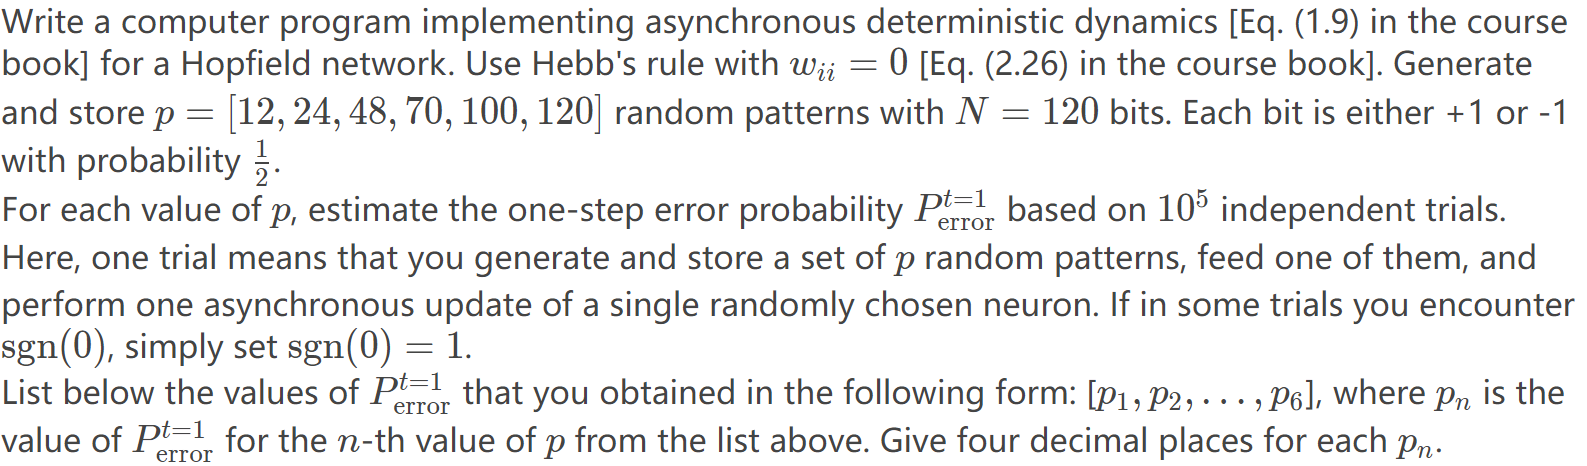

### Hebb's rule

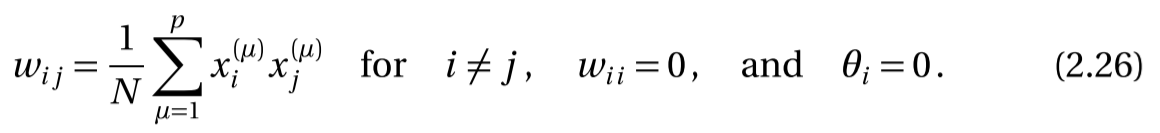

### Asynchronous deterministic updates

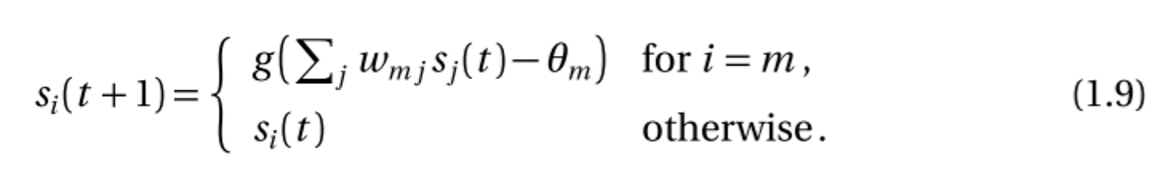

## Initial conditions:

p = [12 24 48 70 100 120] % 24 48 70 100 120 amount of stored patterns

p =     12    24    48    70   100   120


N = 120 % amount of neurons 

N = 120

nTrials = 10e5 % numver of trials

nTrials = 1000000

## Q1: Hebb's rule setting the diagonal weights to zero

% loop through all given numbers
diagonal_zero = true;
P_error_list = [];
for i = 1:length(p)
    P_error_list(end+1) = P_err_cal(p(i), N, nTrials, diagonal_zero);
end

disp("P_error with diagonal elements are 0: ")
out=['[' sprintf(' %.4f, ', P_error_list(1:end-1) ) num2str(P_error_list(end)) ']']

## Q2: Hebb's rule without setting the diagonal weights to zero

diagonal_zero = false;
P_error_list_dz = [];
for i = 1:length(p)
    P_error_list_dz(end+1) = P_err_cal(p(i), N, nTrials, diagonal_zero);
end

disp("P_error with diagonal elements are not 0: ")
out=['[' sprintf(' %.4f, ', P_error_list_dz(1:end-1) ) num2str(P_error_list_dz(end)) ']']

## Loop in trials

function P_error = P_err_cal(p, N, nTrials, diagonal_zero)
    error = 0;
    for trial = 1:nTrials
        % Generate random patterns 120*p
        patterns_generated = 2 * randi([0, 1], N, p) - 1;
        % Initialize weight matrix NxN with Hebb's rule
        W = zeros(N);
        for i = 1:p
            W = W + patterns_generated(:,i)*patterns_generated(:,i)'/N;
        end
        
        % set diagonal elements to 0
        if diagonal_zero == true
            for i = 1:N
                W(i,i) = 0;
            end
        end
    
        % choose a random pattern in the stored patterns 120*1
        pr = patterns_generated(:,randi(p));
        % choose a bit
        nr = randi(N);
    
        % perform update on this bit
%         b_nr = 0;
%         for j = 1:N
%             b_nr = b_nr + W(nr,j)*pr(j);
%         end
        b_nr = W(nr,:)*pr;
        if b_nr == 0
            x_nr = 1;
        else
            x_nr = sign(b_nr);
        end    
        
        % check if the updated bit equals the origin bit
        if x_nr ~= pr(nr)
            error = error + 1;
        end
    end
    P_error = error/nTrials;
end
